## plot one channel's spectrum

chann_num = 1
sample_from_batch_num = 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
spectrum_real = spectral_real(:, chann_num, :);
spectrum_fake = spectral_fake(:, chann_num, :);
spectrum_real = mean(spectrum_real, 1);
spectrum_fake = mean(spectrum_fake, 1);
spectrum_real = spectrum_real(:);
spectrum_fake = spectrum_fake(:);
hold on 
plot(freqs, spectrum_real, 'DisplayName', 'real')
% plot(freqs, spectrum_fake, 'DisplayName', 'fake')
hold off

title('spectrum comparison')
xlabel('frequecy')
ylabel('amplitude')
legend

## plot spectrum for many examples

chann_num = 1

chann_num = 1

sample_from_batch_num = 1

sample_from_batch_num = 1

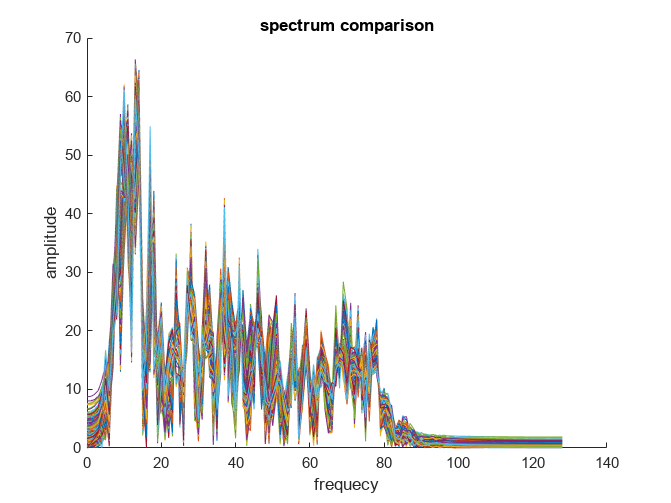

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
spectrum_real = squeeze(spectral_real(:, chann_num, :));
spectrum_fake = squeeze(spectral_fake(:, chann_num, :));
hold on 
plot(freqs, spectrum_real, 'DisplayName', 'real')
% plot(freqs, spectrum_fake, 'DisplayName', 'fake')
hold off

title('spectrum comparison')
xlabel('frequecy')
ylabel('amplitude')

% legend

## plot all channels spectrum

sample_from_batch_num = 1;
clf
% Define the condition for averaging (replace with your specific condition)
average_condition = false;  % Example condition, replace with your logic

if average_condition
  % Calculate average spectrum across channels
  spectrum_real = mean(squeeze(spectral_real(sample_from_batch_num, :, :)), 1);
  spectrum_fake = mean(squeeze(spectral_fake(sample_from_batch_num, :, :)), 1);
else
  spectrum_real = squeeze(spectral_real(sample_from_batch_num, :, :)); 
  spectrum_fake = squeeze(spectral_fake(sample_from_batch_num, :, :));
end

% Plotting
hold_on = true;  % Adjust based on your preference

figure;  % Create a new figure window

if hold_on
  hold on;  % Enable hold for plotting on the same figure
end

plot(freqs, spectrum_real, 'DisplayName', 'Real (Avg)');
plot(freqs, spectrum_fake, 'DisplayName', 'Fake (Avg)');

if hold_on
  hold off;  % Disable hold if using hold_on
end

title('Spectrum Comparison (Conditional Average)');
xlabel('Frequency');
ylabel('Amplitude');
legend;


## plot one channel's raw samples

chann_num = 1

chann_num = 1

sample_from_batch_num = 7

sample_from_batch_num = 7

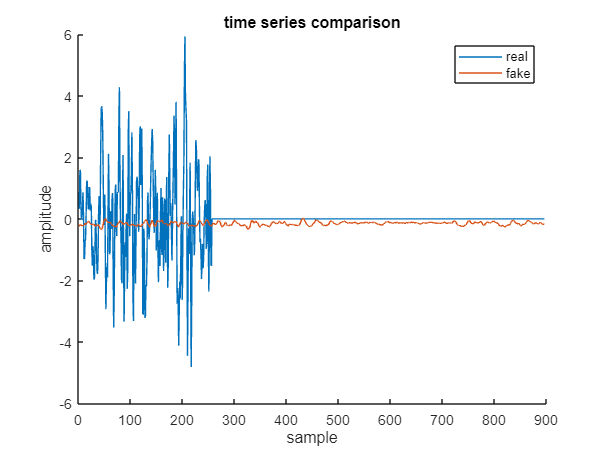

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, chann_num, :));
signal_fake = squeeze(X_fake(sample_from_batch_num, chann_num, :));
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot all channels raw samples

sample_from_batch_num = 11
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, :, :))';
signal_fake = squeeze(X_fake(sample_from_batch_num, :, :))';
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot one channel's spectrum calculated from raw signals

clf
% plot_fft_stats(X_real)

X=X_real(:,:,1:256); % remove latest zero values
X = permute(X, [3 1 2]);
% if nargin == 1
name = '';
% end
Fs = 256;
L = 256;
BS=buffer(X,256,0);
P1_all = zeros([size(BS, 2), 129]);
BS = X;
for i = 1:size(BS, 2)
    f = Fs*(0:(L/2))/L;
    Y = fft(BS(:, i)');
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--', 'DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-avg']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-min']));
% plot(f,P1_means+std(P1_all, [], 1),'--');
% plot(f,P1_means-std(P1_all, [], 1),'--');
legend
hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")

## raw time series with transparency

% need to check
figure;
data = data_real(:);
hold on;
color = 'g';  % Adjust color as needed
colormap = [0 0 1; 1 0.5 0];
for i = 1:floor(length(data)/10):length(data)
%     plot(data(1:i), colormap(mod(i, size(colormap, 1))+1), 'LineWidth', 1, 'LineStyle', '-.');  % Adjust line style and width
    plot(data(1:i), color, 'LineWidth', 1, 'LineStyle', '-.');  % Adjust line style and width
end
hold off;
xlabel('Time (Index)');
ylabel('Data Value');
title('Time Series Plot with Transparency (Line Style)');


## calculate statistics from signals

chann_idx = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Calculate statistics from real data
stats_real = calculate_statistics(X_real(:,chann_idx,:));
% Access results
disp('Real data statistics');
disp(['Mean: ', num2str(stats_real.mean)]);
disp(['Standard deviation:', num2str(stats_real.std)]);
disp(['Minimum value:', num2str(stats_real.min)]);
disp(['Maximum value:', num2str(stats_real.max)]);

% Calculate statistics from fake data
stats_fake = calculate_statistics(X_fake(:,chann_idx,:));
% Access results
disp('Fake data statistics');
disp(['Mean: ', num2str(stats_fake.mean)]);
disp(['Standard deviation:', num2str(stats_fake.std)]);
disp(['Minimum value:', num2str(stats_fake.min)]);
disp(['Maximum value:', num2str(stats_fake.max)]);

## plot histogram

chann_idx = 1;
n_examples = min(size(X_real, 1), size(X_fake, 1))
nbins = [10, 20];
data_real = X_real(1:n_examples,chann_idx,:);
data_fake = X_fake(1:n_examples,chann_idx,:);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot_histograms_real_fake(data_real, data_fake, nbins);

## Kernel Density Estimation

chann_idx = 1;
data_real = X_real(:,chann_idx,:);
data_fake = X_fake(1:160,chann_idx,:);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf;
plot_kernel_density_estimations(data_real, data_fake);

## Boxplot

% need to 
figure;
% hold on
boxplot(data_real(:));
boxplot(data_fake(:));
% hold off
xlabel('Data');
ylabel('Value');
title('Box Plot of Time Series Data');

## 2D projections

n_examples = min(size(X_real, 1), size(X_fake, 1))
chann_idx = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data_real = X_real(1:n_examples,chann_idx,:);
data_fake = X_fake(1:n_examples,chann_idx,:);
data_real = reshape(data_real, [size(data_real, 1) size(data_real, 3)]);
data_fake = reshape(data_fake, [size(data_fake, 1) size(data_fake, 3)]);

plot_pca_projections(data_real, data_fake);
plot_tsne_projections(data_real, data_fake);

## functions

function plot_fft_stats_already_buffered(X, name)
if nargin == 1
    name = '';
end
Fs = 256;
L = 256;
% BS=buffer(X,256,0);
% P1_all = zeros([size(BS, 2), 129]);
BS = X;
for i = 1:size(BS, 2)
    f = Fs*(0:(L/2))/L;
    Y = fft(BS(:, i)');
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--', 'DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-avg']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-min']));
% plot(f,P1_means+std(P1_all, [], 1),'--');
% plot(f,P1_means-std(P1_all, [], 1),'--');
legend
hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")
end

function stats = calculate_statistics(data)

%   This function calculates statistics (mean, standard deviation, minimum, maximum)
%   from a 3D MATLAB array.
%   Args:
%       data: A 3D MATLAB array.
%   Returns:
%       A structure 'stats' containing the calculated statistics.

  % Input validation
  if size(data, 2) ~= 1
    error('Input data must be a 3D matrix with a single channel.');
  end
  data = permute(data, [1 3 2]);
  % Calculate statistics
  stats.mean = mean(data, "all");
  stats.std = std(data, 0,"all");
  stats.min = min(data(:));  % Use colon (:) for all elements
  stats.max = max(data(:));

end

function plot_histograms_real_fake(data_real, data_fake, nbins)
  clf

  % Get minimum and maximum values from both data sets
  min_value = min(cat(1, data_real, data_fake), [], 'all');
  max_value = max(cat(1, data_real, data_fake), [], 'all');

  % Number of subplots based on the length of nbins vector
  num_subplots = length(nbins);

  % Loop through each nbins value and create subplots
  for i = 1:num_subplots
    current_nbins = nbins(i);
    bin_width = (max_value - min_value) / current_nbins;
    edges = linspace(min_value, max_value, current_nbins + 1);

    % Create subplot for each nbins value
    subplot(num_subplots, 1, i);

    % Plot histograms for real and fake data
    hold on
    hist_real = histogram(data_real, edges, 'DisplayName', 'real');
    hist_fake = histogram(data_fake, edges, 'DisplayName', 'fake');
    hold off

    % Adjust subplot title and labels (optional)
    title(sprintf('%.0f bins', current_nbins));
    xlabel('Data Values');
    ylabel('Frequency');
    legend;
  end

  % Adjust overall figure title and labels (optional)
  sgtitle('Data Histograms');  % Sets title for the whole figure
  xlabel('Data Values');
  ylabel('Frequency');
end

function plot_pca_projections(data_real, data_fake)
% Assuming your matrices are named 'mat1' and 'mat2'
[coeff1, score1, latent1] = pca(data_real);  % Perform PCA on matrix 1
[coeff2, score2, latent2] = pca(data_fake);  % Perform PCA on matrix 2

% Select the desired number of principal components (e.g., 2 for 2D plot)
num_components = 2;

% Project data onto principal components
projected_mat1 = score1(:, 1:num_components);
projected_mat2 = score2(:, 1:num_components);

% Create the PCA plot
scatter(projected_mat1(:, 1), projected_mat1(:, 2), 'b', 'o', 'DisplayName', 'Real');
hold on;
scatter(projected_mat2(:, 1), projected_mat2(:, 2), 'r', 's', 'DisplayName', 'Fake');
title('PCA Visualization');
xlabel('Principal Component 1');
ylabel('Principal Component 2');
legend('show');
grid on;
hold off;
end

function plot_tsne_projections(data_real, data_fake)
mapped_data1 = tsne(data_real, 'NumDimensions', 2, 'Distance', 'euclidean', 'Perplexity', 10);  % Perform t-SNE on matrix 1 with 2 dimensions
mapped_data2 = tsne(data_fake, 'NumDimensions', 2, 'Distance', 'euclidean', 'Perplexity', 10);  % Perform t-SNE on matrix 2 with 2 dimensions

% Create the t-SNE plot
figure;
scatter(mapped_data1(:, 1), mapped_data1(:, 2), 'b', 'o', 'DisplayName', 'Real');
hold on;
scatter(mapped_data2(:, 1), mapped_data2(:, 2), 'r', 's', 'DisplayName', 'Fake');
title('t-SNE Visualization');
xlabel('t-SNE Dimension 1');
ylabel('t-SNE Dimension 2');
legend('show');
grid on;
hold off;
end

function plot_kernel_density_estimations(data_real, data_fake)
hold on 
[density_real, ~] = ksdensity(data_real(:));
plot(density_real);
[density_fake, ~] = ksdensity(data_fake(:));
plot(density_fake);
hold off
xlabel('Data Value');
ylabel('Density');
title('KDE Plot of Time Series Data');
end